# Signals #4: orthogonal discrete Fourier transform (DFT)

## DFT and inverse DFT matrices

DFT is an orthogonal transfornation of a signal $\mathbf{x}=[x(0),x(1),...,x(N-1)]^T$, specified by a complex-value DFT synthesis matrix $\mathbf{S}$ ($j=\sqrt{-1}$):

$S[n,k]=\sqrt{\frac{1}{N}} \exp \left( j \frac{2 \pi}{N} kn \right) = \sqrt{\frac{1}{N}} \cos \left(  \frac{2 \pi}{N} kn \right) + j \sqrt{\frac{1}{N}} \sin \left( \frac{2 \pi}{N} kn \right), \qquad k,n=0,1,2,...,N-1$.

The DCT, DST, Walsh-Hadamard and Haar transformations, investigated in laboratory 3, have real-value matrices. The analysis DFT matrix is equal $\mathbf{A}=\mathbf{S}^{*T}$(conjugation, transposition).

**Analyze the Matlab code**. Carefully observe shapes of signals present of matrix `S` columns: in their real and imaginary part. Do zooming. Check columns one by one.

% DFT transformation matrices
clear all; close all;
N = 40;                      % matrix dimension
k = (0:N-1); n=(0:N-1);      % rows=functions, columns=samples
S = exp(j*2*pi/N*n'*k);      % synthesis matrix without scaling
A = S';                      % analysis matrix: conjugation + transposition
S*A,                         % checking matrix orthogonality, N on the diagonal

ans =   40.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i  40.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.

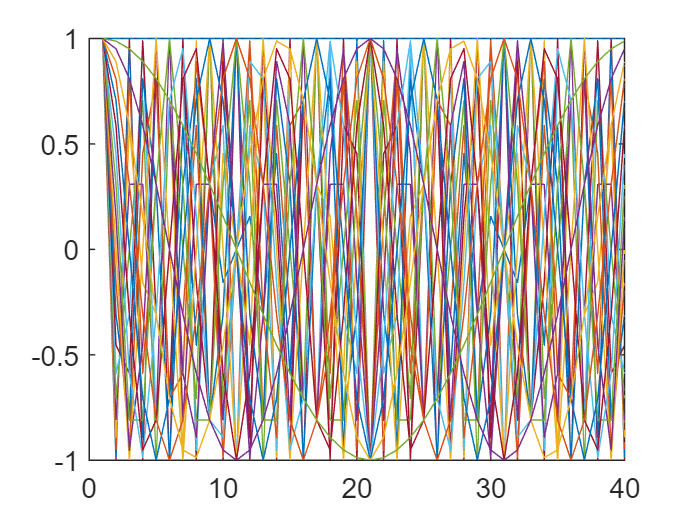

figure; plot(real(S));       % real(S) - cosines, imag(S) - sines, add viewing columns one by one

## DFT and inverse DFT transform

The DFT signal analysis and synthesis equations (direct and inverse transformations) are defined the same way as in laboratory 3:


$$\mathbf{X}=\mathbf{S}^{*T} \mathbf{x}, \qquad \hat{\mathbf{x}}=\mathbf{S X}$$


For this reason the output values $\mathbf{y}=[y(0), y(1),...,y(N-1)]^T$ are complex-value also: their real parts describe an analyzed signal similarity to cosines while the imaginary parts - to sines, both for consecutive frequencies:


$$f_k=kf_0, \quad f_0=\frac{1}{N \cdot dt}=\frac{f_s}{N}, \quad k=0,1,2,...,N-1.$$


**Analyze the Matlab code**. Add frequency scaling to the horizontal axis. Add more signals, even very strange. Is the reconstruction error always very close to zero? Can you deduce from the DFT spectrum what is the signal frequency? When signal has a few different frequency components, can you remove one of them?

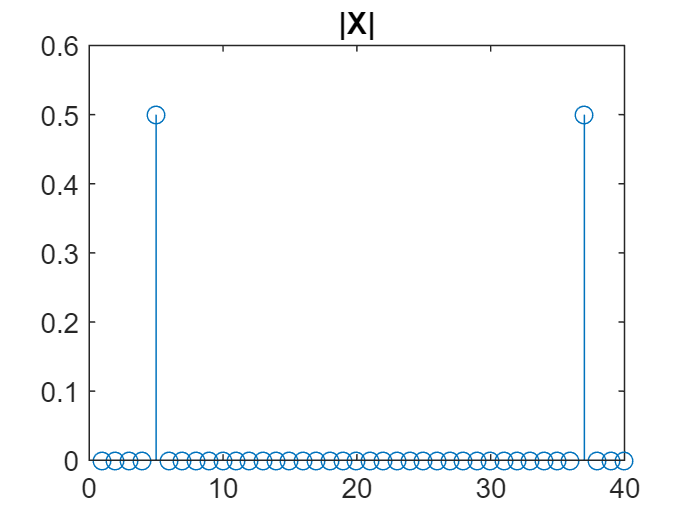

% DFT and inverse DFT: "soup --> finding its receipt --> opt. modification --> boiling a soup"
% x = rand(N,1);             % random signal to be transformed: analysed and reconstructed
x = real(S(:,5));            % choose real, imag, nothing
X = (1/N)*A*x;               % DFT-based analysis
%X(5)=0; X(N-5+1)=0;         % optional removing some components
xhat = S*X;                  % inverse DFT-based synthesis
stem(abs(X)); title('|X|');  % DFT transformation result

error = max(abs(x-xhat)),    % reconstruction error

error = 7.8697e-15

##  DFT-based frequency analysis

**Analyze the Matlab code**. Below we have modified the program from laboratory 3, adjusting it to DFT. Choose different input signals, starting from the simplest ones, observe real&imaginary parts of DFT as well as magnitude and angle of its complex-value numbers. Knowing equation of the analyzed signal basic component:

$x_k(n)=A_k \cos(2\pi f_k t + \varphi_k)$,

can you "read" values of $\{ a_k, f_k, \varphi_k \}$ from the DFT spectrum magnitude $X(f)$ plot? Can you conclude that the result is correct? What is surprising for you?

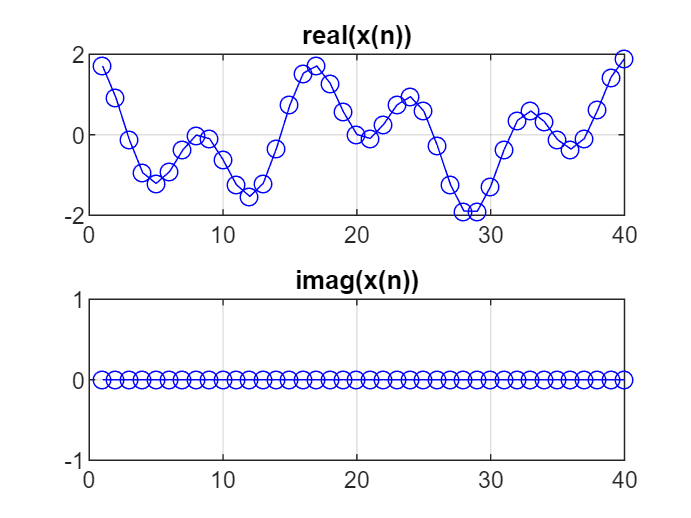

% Signal: first single cosine or sine, with frequency k*f0 or different, then sums of pure signals
fs=1000; dt=1/fs; t=dt*(0:N-1)';   % sampling frequency, sampling perid, time moments
T=N*dt; f0=1/T; fk = f0*(0:N-1);   % time duration of signal, the lowest frequency, its multiplis
x1 = 1*cos(2*pi*(2*f0)*t + pi/5);  % signal 1:  2*f0  or  2.5*f0, cos or sin, pi/4 or 0
x2 = 1*cos(2*pi*(5*f0)*t + pi/7);  % signal 2:  5*f0  or  5.5*f0, cos or sin, pi/7 or 0 
x3 = 0.001*cos(2*pi*(10*f0)*t);    % signal 3: 10*f0  or 10.5*f0, cos or sin
x = x1+x2;                         % choice: x1, x2, x3, x1+x2, x2+x3
figure;                            % output
subplot(211); plot(real(x),'bo-'); title('real(x(n))'); grid;
subplot(212); plot(imag(x),'bo-'); title('imag(x(n))'); grid;

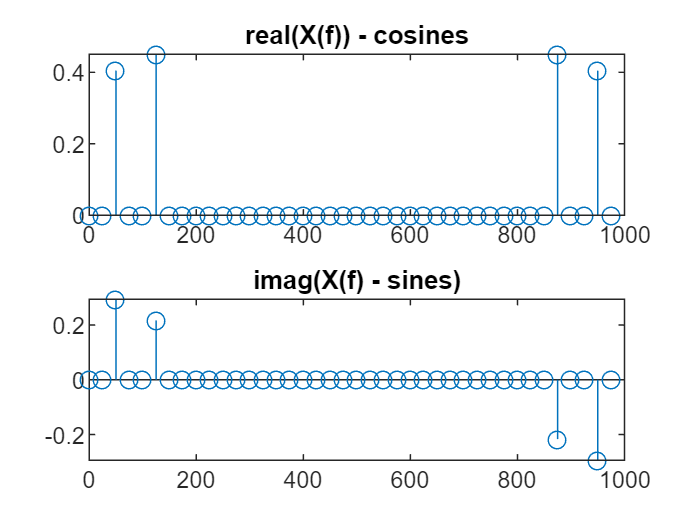


% DFT of the signal
X = (1/N)*A*x;                     % our code, with Matlab function: X=fft(x.')/N;
figure;                            % DFT spectrum interpretation
subplot(211); stem(fk,real(X),'o-'); title('real(X(f)) - cosines');
subplot(212); stem(fk,imag(X),'o-'); title('imag(X(f) - sines)');

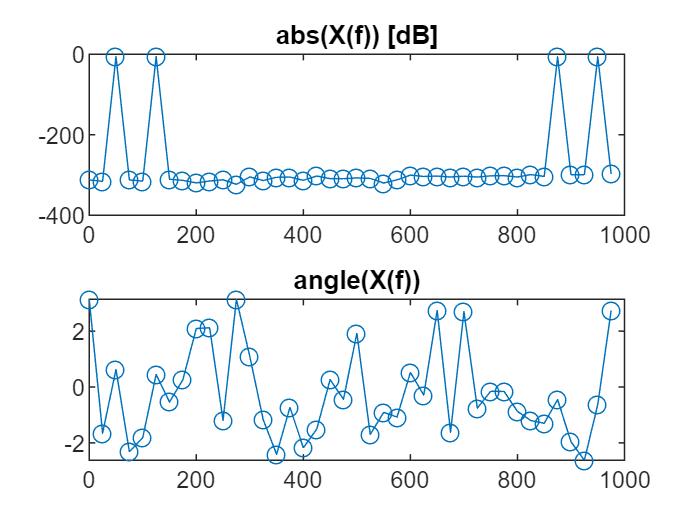

figure; 
subplot(211); plot(fk,20*log10(abs(X)),'o-'); title('abs(X(f)) [dB]');
subplot(212); plot(fk,angle(X),'o-'); title('angle(X(f))')

## DFT-based signal filtration

When we are modifying DFT spectrum and performing inverse DFT, we are synthesizing signal having some components removed, i.e. we perform signal filtration in DFT spectrum domain (frequency domain) .

**Analyze the Matlab code**. Observe that componet no 5 i removed from the signal. Generate different multi-component signals. Remove some components. Remove some frequencies from your own speech signal (first record the speech).   

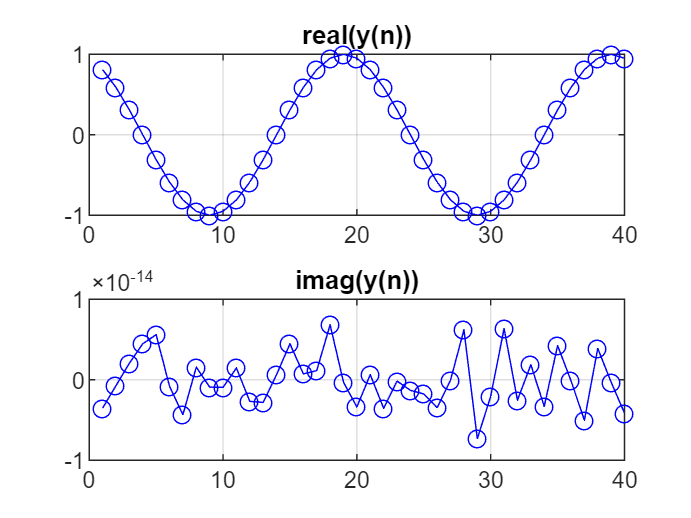

% DFT spectrum modification
X(1+5)=0; X(N-5+1)=0;              % removing signal x2 with freq. 5*f0

% Inverse DFT - signal synthesis
y = S*X;                           % signal reconstruction, with Matlab function: y=N*ifft(X); 
figure;                            % output
subplot(211); plot(real(y),'bo-'); title('real(y(n))'); grid;
subplot(212); plot(imag(y),'bo-'); title('imag(y(n))'); grid;

error = max(abs(x-real(y))),      % signal reconstruction error

error = 0.9439